## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from GLE model with potential=0.5*psi*x^2

This scrip just changing para by hand and make the frame of simulation.

## GLENII fv0 Intro

change FDE into GLENII

## GLENII fv02 Intro

try to plot each MSD data together

## FDEWRB fv02 Intro

change GLE to FDE

## Import data and previewing

The data come from expomential fitness data.

data_list=["p47","p77","p179","n78","n142","n589"];
genomic_distance=[47+6,77+6,179+6,78+50,142+50,589+50];
modelfun= @(x,theta) FDEWRB_get_MSD(theta(1),theta(2),theta(3),x);
figure(1);clf
xlabel('t  /  s','FontSize',14);
ylabel('MSD / m^2','FontSize',14);
%title({['processed experiment MSD & FDEWRB simulation MSD -t'],['processed experiment data: ']},'Color','r','FontSize',10);
title({'FDE with reflecting boudary';''},'FontSize',20)
set(gca,'xscale','log');
set(gca,'yscale','log');
parameter_history=[];

data_location1='C:\Users\zhouquan\OneDrive\research\scrips\processed_data';
data_location2='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.05图像\GLENII';
for n_data=1:length(data_list)
    data_name_char=data_list(n_data);
    data_name=char(data_name_char);
    selecting_curve='xy';
    
    data_mode="mixed data";%data mode is "processed data" or "mixed data"
    Selecting_Mode='discard'; %'discard','average'
    
    if data_name_char=="n589"
        data_mode="initial data";
    end
    
    if data_mode=="processed data"
        experiment_interval=30;
        min_length=40;
        time_scale=experiment_interval*(1:min_length);
        
        load([data_location1,' ',data_name,'_',num2str(experiment_interval),'s.mat'])
        
        fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
        t=time_scale;
        a(1)=2.542e+05;%n142_30s
        a(2)=9.705e-05;
        a(3)=-1.391e+05;
        a(4)=-0.01086;
        
        Reserved_length=min_length;
        interceptive_experiment_MSD=[time_scale;1e-18*fun(a,time_scale)];
    elseif data_mode=="mixed data"
        interceptive_experiment_MSD=[];
        load([data_location1,'\mixed data ',data_name,' ', Selecting_Mode,'.mat'])
        for i=1:length(t_mixMSD(1,:))
            if t_mixMSD(1,i)<=1200
                interceptive_experiment_MSD=[interceptive_experiment_MSD,[t_mixMSD(1,i);1e-18*t_mixMSD(2,i)]];
            end
        end
    elseif data_mode=="initial data"
        experiment_interval=30;
        interceptive_experiment_MSD=[];
        load([data_location1,'\processed data ',data_name,'_30s.mat'])
        for i=1:reserved_length
            interceptive_experiment_MSD=[interceptive_experiment_MSD,[experiment_interval*i;1e-18*processed_MSD(i)]];
        end
    end

## Parameter importing

    kB=1.3806505e-23;
    T=293;%confirmed

    if data_name_char=="n589"

        mpsi=1.20345e-08;

        zeta=3.7811e-07;

        H=0.64058;

    else

        load([data_location2,'\mcmc result ',data_name,'.mat'])

        GLE_input=mean(chain);

        average_para=[mean(chain(:,1)),mean(chain(:,2)),mean(chain(:,3))];

        err_para=[0,0,0];

        name_para=["m*\psi","\zeta","H"];

        for i=1:3

            error_para(1,i)=(sum((chain(:,i)-average_para(i)).^2)/(length(chain(:,i))*(length(chain(:,i))-1)))^0.5;

        end

        %m=GLE_input(1);

        %psi=GLE_input(2);

        mpsi=GLE_input(1);

        zeta=GLE_input(2);

        H=GLE_input(3);

    end

    if data_name_char=="n589"
        INPUT=[1.4573e-06  , 0.62456  , 1.09373e-14];
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    elseif data_name_char=="p47"
        INPUT=[6.0086e-07  , 0.55727 , 9.3167e-15] ;
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    elseif data_name_char=="p77"
        INPUT=[7.9325e-07  , 0.68138  , 7.1091e-15] ;
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    elseif data_name_char=="p179"
        INPUT=[1.11078e-06 , 0.49278  , 1.57003e-14  ];
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    elseif data_name_char=="n78"
        INPUT=[1.13521e-06 , 0.50504  , 1.59103e-14 ] ;
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    elseif data_name_char=="n142"
        INPUT=[9.7171e-07  , 0.51216  , 1.60487e-14] ;
        a=INPUT(1);
        Gamma=INPUT(2);
        K_gamma=INPUT(3);
    end

## Main loop

    simulation_MSD=[];
    for t=interceptive_experiment_MSD(1,:)
        sum_number=10;
        sum_list=zeros(sum_number,1);
        for m=1:sum_number
            sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
        end
        simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
    end
    


## Plot and saving

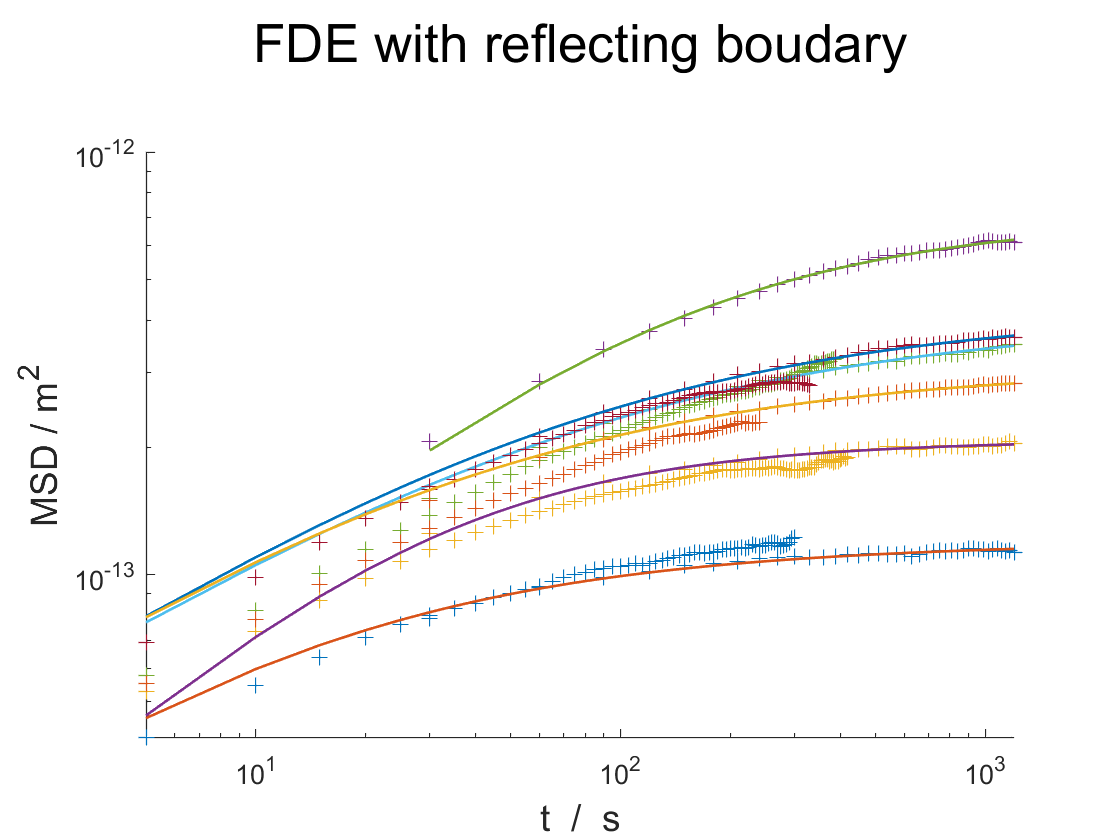

    figure(1)
    hold on

    plot(interceptive_experiment_MSD(1,:),interceptive_experiment_MSD(2,:),'+','displayname', data_name)
    %plot(time_scale,1e-18*processed_MSD(1:min_length),'+',"DisplayName",'experiment xy average data',"Color",'cyan',"LineWidth",1)
    %legend_name=strcat('GLENII simulation MSD',' m*\psi= ',num2str(mpsi),'m \zeta=',num2str(zeta),' H= ',num2str(H));
    legend_name=['simulation MSD of ',data_name];
    plot(sort(interceptive_experiment_MSD(1,:)),sort(simulation_MSD),"LineWidth",1,'displayname',legend_name)
    %legend('Location','eastoutside');
    
end